# Section 6

## 1

clear
n = 25;
u = ones(n,1);
u(2) = 2;
for i=3:n
    u(i) = u(i-2) + u(i-1);
end

u(n)

ans = 121393

## 2

## 7

clear
fprintf("Problem 6.7")

Problem 6.7

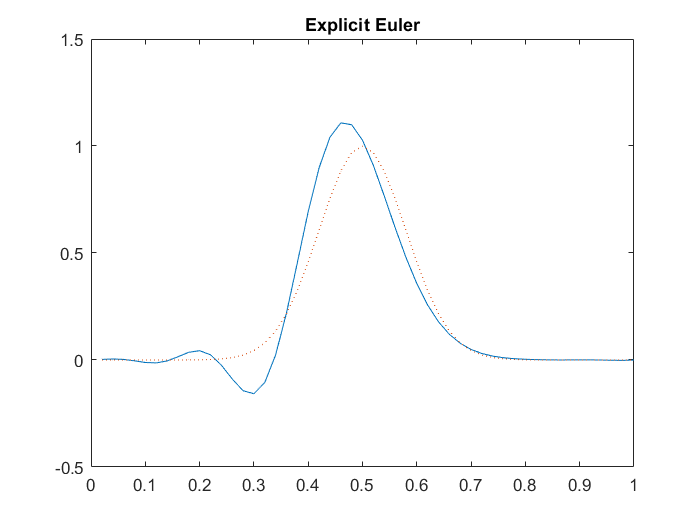

% PARAMETERS
a = 1;
Cn = 0.1;
M = 50;
dx = 1 / M;
dt = Cn * dx ./ a;
N = 1 * round(1/dt);
x = dx:dx:1;

A = -a ./ (dx) * MAT_DIFF_OPERATOR2(M);
% DIFFUSION EQUATION % dudt = - a dudx
f = @(t, u) (A * u);

% INITIAL CONDITION
ic = @(x) exp(-0.5 * ((x-0.5) ./ 0.08) .^ 2);


% TIME MARCHING

u2 = RUNGEKUTTA4(M, N / 10, f, ic(x), 10 * dt);

u3 = TWO_STEP_LINEAR_METHOD(M, N, ic(x), dt, A, 0, 0, 0, 0); % EXPLICIT EULER Cn = 0.1
u4 = TWO_STEP_LINEAR_METHOD(M, N / 10, ic(x), 10 * dt, A, 0, 1, 0, 0); % IMPLICIT EULER Cn = 1
u5 = TWO_STEP_LINEAR_METHOD(M, N / 10, ic(x), 10 * dt, A, 0, 1/2, 0, 0); % AM2 / Trapezoidal Cn = 1
u6 = TWO_STEP_LINEAR_METHOD(M, N, ic(x), dt, A, 0, 0, 0, 1/2); % AB2 Cn = 0.1

%% PLOT FINAL STATE % n = 1000

% plot(x, ic(x));
% ylim([-0.5 1.5])
% 
% hold on
% plot(x, u3(:, N));
% plot(x, u4(:, N/10));
% plot(x, u5(:, N/10));
% plot(x, u6(:, N));
% plot(x, u2(:, N/10));
% 
% hold off
% legend('Initial Condition', 'Euler', 'Implicit Euler', 'AM2 / Trapezoidal', 'AB2', 'RK4');

plot(x, u3(:, N), x, ic(x), ':');
title('Explicit Euler')
ylim([-0.5 1.5])

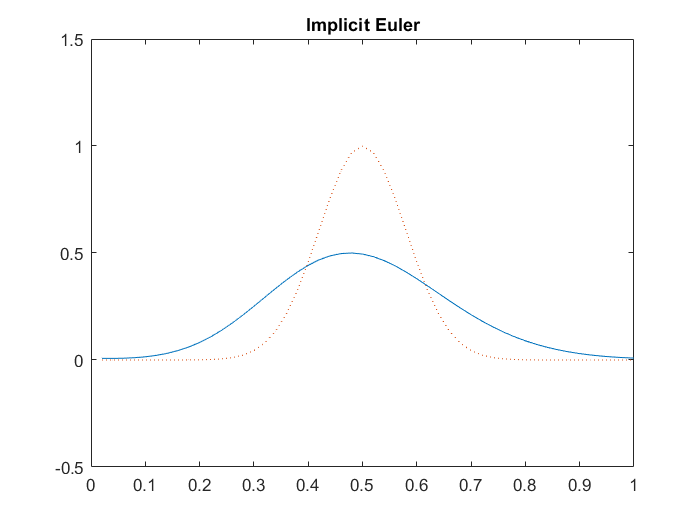


plot(x, u4(:, N/10), x, ic(x), ':');
title('Implicit Euler')
ylim([-0.5 1.5])

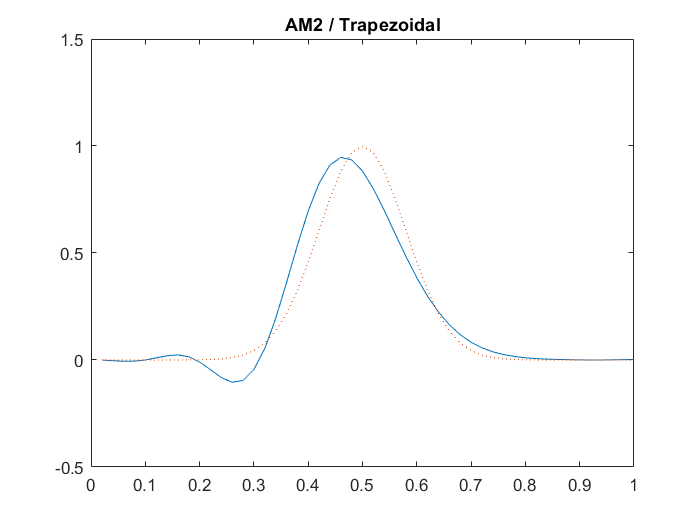


plot(x, u5(:, N/10), x, ic(x), ':');
title('AM2 / Trapezoidal')
ylim([-0.5 1.5])

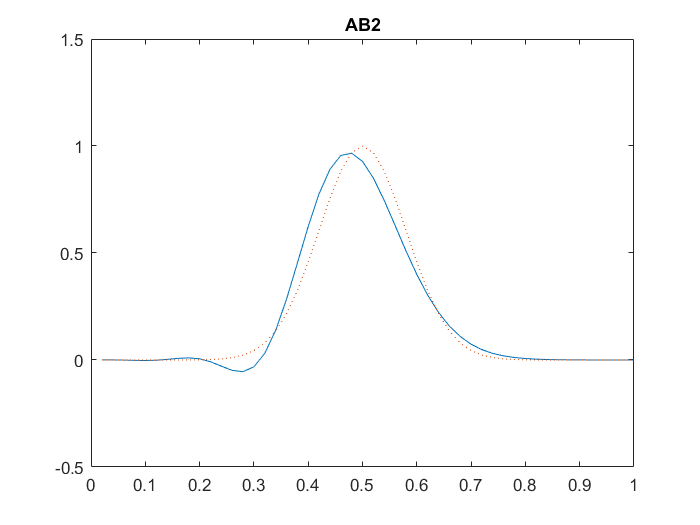


plot(x, u6(:, N), x, ic(x), ':');
title('AB2')
ylim([-0.5 1.5])

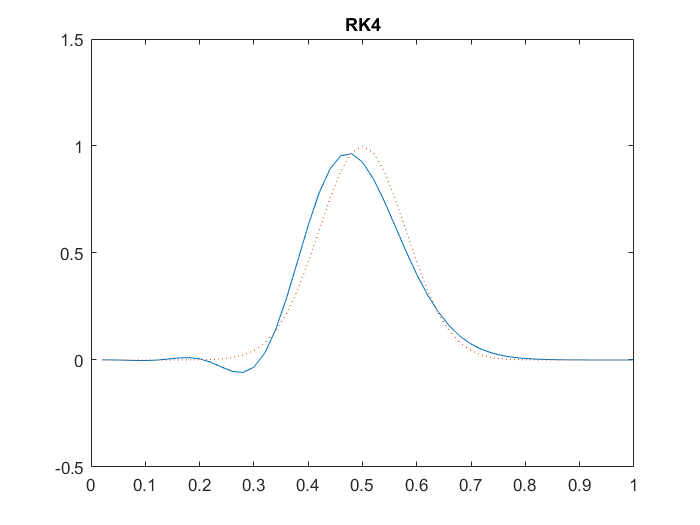


plot(x, u2(:, N/10), x, ic(x), ':');
title('RK4')
ylim([-0.5 1.5])

## 8

clear
fprintf("Problem 6.8")

Problem 6.8

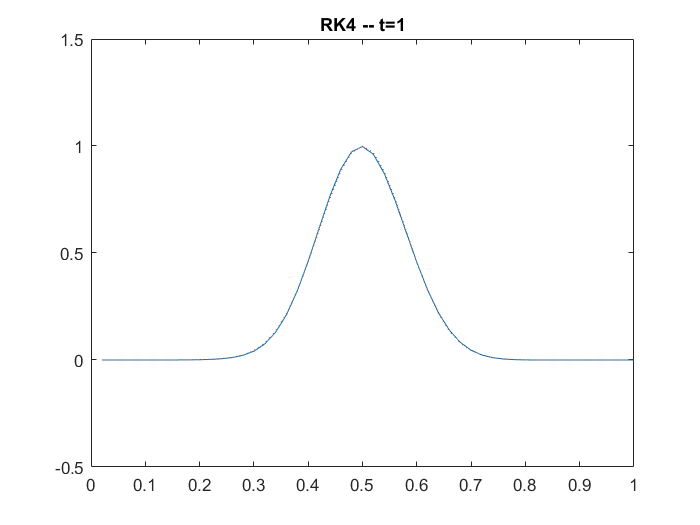

% PARAMETERS
a = 1;
Cn = 1;
M = 50;
dx = 1 / M;
dt = Cn * dx ./ a;
N = 10 * round(1/dt);
x = dx:dx:1;

% 2nd order centered spatial difference operator
A = -a ./ dx * MAT_DIFF_OPERATOR4(M);

% DIFFUSION EQUATION % dudt = - a dudx
f = @(t, u) A * u ;

% INITIAL CONDITION
ic = @(x) exp(-0.5 * ((x-0.5) ./ 0.08) .^ 2);

% TIME MARCHING

T1 = 'RK4 -- t=1';
T2 = 'RK4 -- t=10';
u1 = RUNGEKUTTA4(M, N, f, ic(x), dt);


P1 = plot(x, u1(:, N/10), x, ic(x), ':');
title(T1)
ylim([-0.5 1.5])

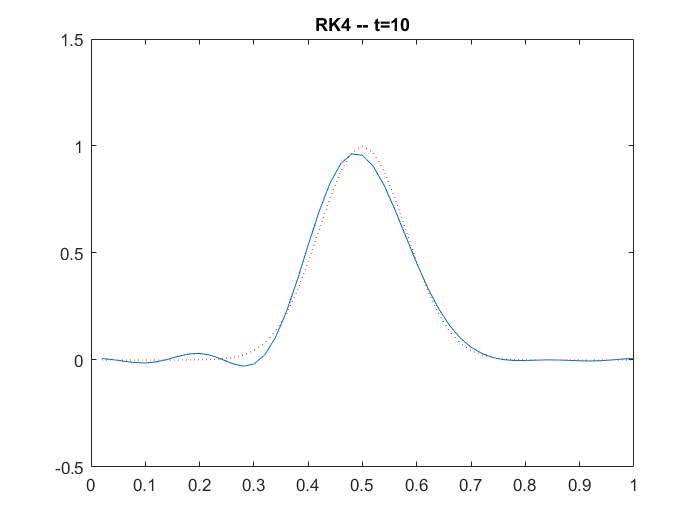


P2 = plot(x, u1(:, N), x, ic(x), ':');
title(T2)
ylim([-0.5 1.5])

## 9

clear
fprintf("Problem 6.9")

Problem 6.9

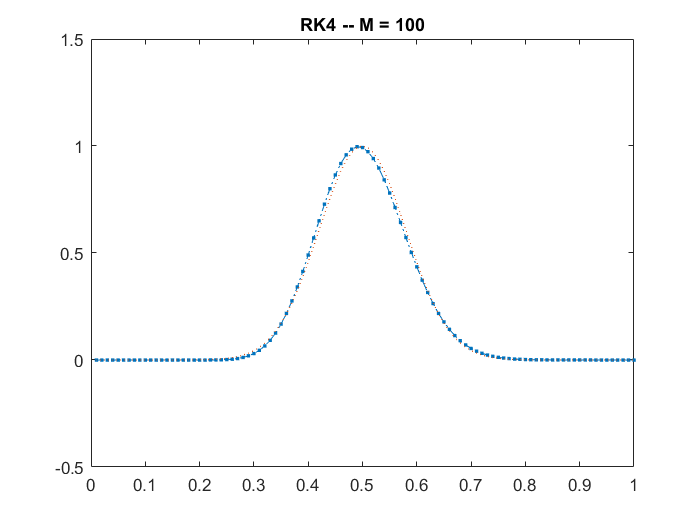

% PARAMETERS
a = 1;
Cn = 1;
M = 100;
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(1/dt);
x = dx:dx:1;

er = zeros(1,3);

% 2nd order centered spatial difference operator
A = -a./ dx * MAT_DIFF_OPERATOR2(M);
f = @(t, u) A * u ;

% INITIAL CONDITION
ic = @(x) exp(-0.5 * ((x-0.5) ./ 0.08) .^ 2);

% TIME MARCHING
T1 = 'RK4 -- M = 100';
u1 = RUNGEKUTTA4(M, N, f, ic(x), dt);
P1 = plot(x, u1(:, N),'.-.', x, ic(x), ':');
title(T1)
ylim([-0.5 1.5])

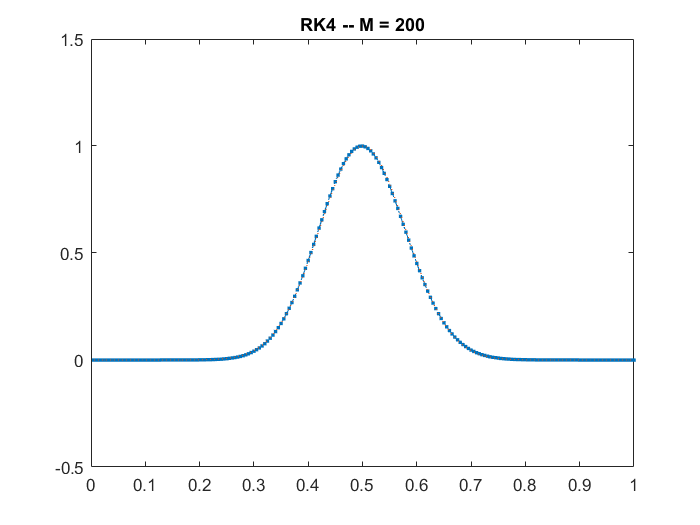

er(1) = sqrt(sum((ic(x)' - u1(:, N)).^2) ./ M);

% PARAMETERS
M = 200;
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(1/dt);
x = dx:dx:1;

% 2nd order centered spatial difference operator
A = -a./ dx * MAT_DIFF_OPERATOR2(M);
f = @(t, u) A * u ;

% TIME MARCHING
T2 = 'RK4 -- M = 200';
u2 = RUNGEKUTTA4(M, N, f, ic(x), dt);
P2 = plot(x, u2(:, N),'.-.', x, ic(x), ':');
title(T2)
ylim([-0.5 1.5])

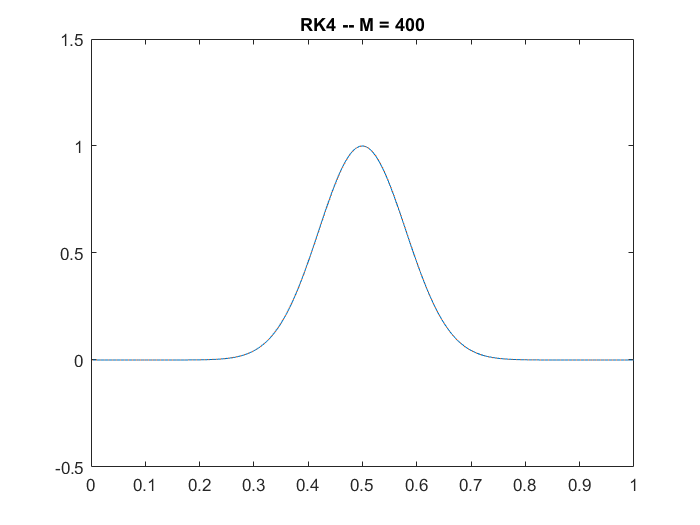

er(2) = sqrt(sum((ic(x)' - u2(:, N)).^2) ./ M);


% PARAMETERS
M = 400;
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(1/dt);
x = dx:dx:1;

% 2nd order centered spatial difference operator
A = -a./ dx * MAT_DIFF_OPERATOR2(M);
f = @(t, u) A * u ;

% TIME MARCHING
T3 = 'RK4 -- M = 400';
u3 = RUNGEKUTTA4(M, N, f, ic(x), dt);
P3 = plot(x, u3(:, N), x, ic(x), ':');
title(T3)
ylim([-0.5 1.5])

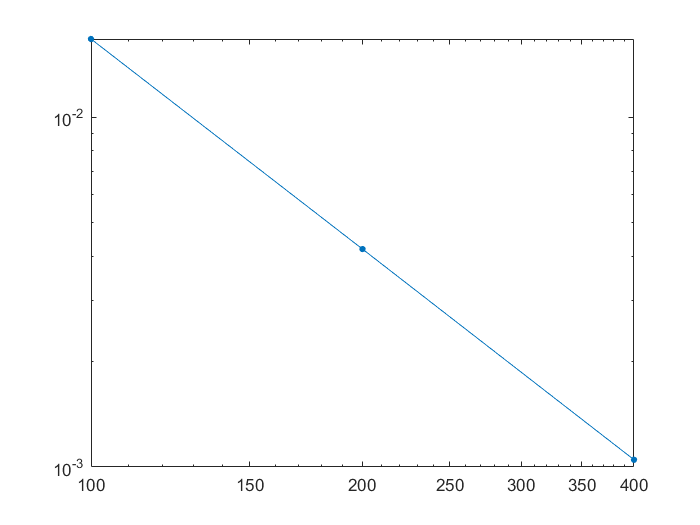

er(3) = sqrt(sum((ic(x)' - u3(:, N)).^2 ./ M));

% ERROR
loglog([100 200 400], er, '.-','MarkerSize', 13);

er(1)/er(1)

ans = 1

er(1)/er(2)

ans = 3.9847

er(1)/er(3)

ans = 15.9350

Order 2

## 10

clear
fprintf("Problem 6.10")

Problem 6.10

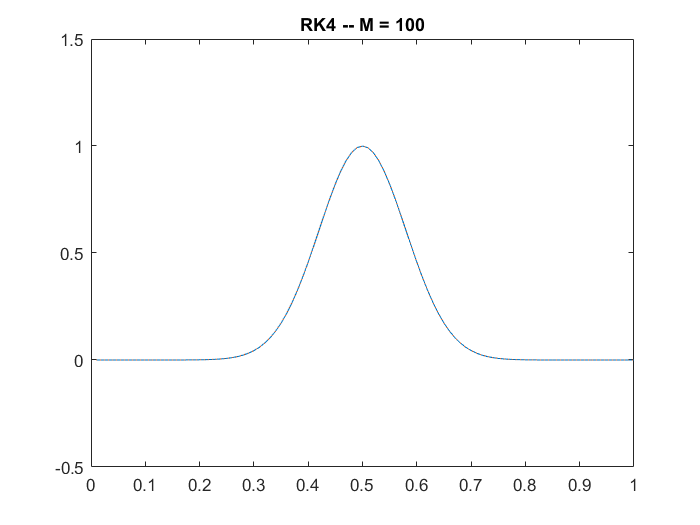

% PARAMETERS
a = 1;
Cn = 1;
M = 100;
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(1/dt);
x = dx:dx:1;

er = zeros(1,3);

% 4th order centered spatial difference operator
A = -a ./ dx * MAT_DIFF_OPERATOR4(M);
f = @(t, u) A * u ;

% INITIAL CONDITION
ic = @(x) exp(-0.5 * ((x-0.5) ./ 0.08) .^ 2);

% TIME MARCHING
T1 = 'RK4 -- M = 100';
u1 = RUNGEKUTTA4(M, N, f, ic(x), dt);
P1 = plot(x, u1(:, N), x, ic(x), ':');
title(T1)
ylim([-0.5 1.5])

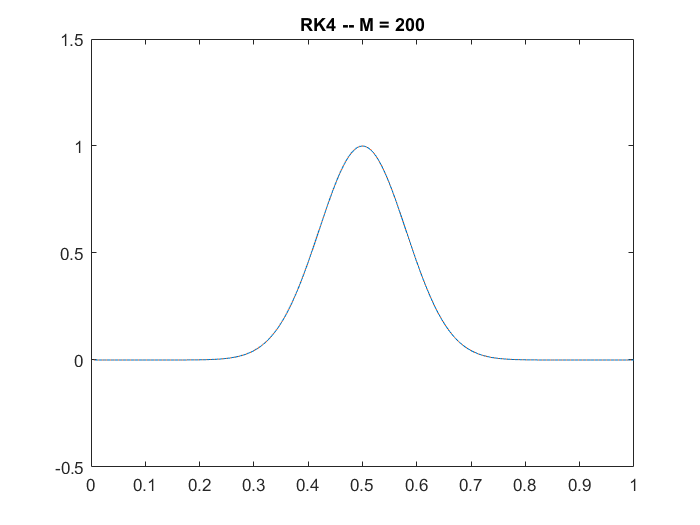

er(1) = sqrt(sum((ic(x)' - u1(:, N)).^2) ./ M);

% PARAMETERS
M = 200;
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(1/dt);
x = dx:dx:1;

% 4th order centered spatial difference operator
A = -a ./ dx * MAT_DIFF_OPERATOR4(M);
f = @(t, u) A * u ;

% TIME MARCHING
T2 = 'RK4 -- M = 200';
u2 = RUNGEKUTTA4(M, N, f, ic(x), dt);
P2 = plot(x, u2(:, N), x, ic(x), ':');
title(T2)
ylim([-0.5 1.5])

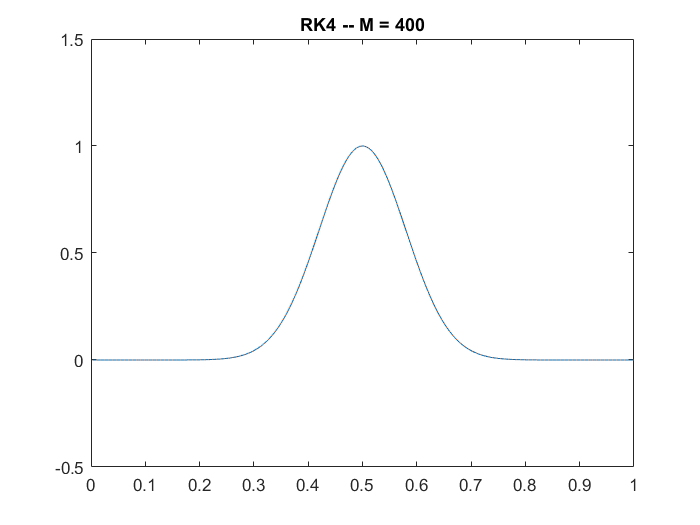

er(2) = sqrt(sum((ic(x)' - u2(:, N)).^2) ./ M);


% PARAMETERS
M = 400;
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(1/dt);
x = dx:dx:1;

% 4th order centered spatial difference operator
A = -a ./ dx * MAT_DIFF_OPERATOR4(M);
f = @(t, u) A * u ;

% TIME MARCHING
T3 = 'RK4 -- M = 400';
u3 = RUNGEKUTTA4(M, N, f, ic(x), dt);
P3 = plot(x, u3(:, N), x, ic(x), ':');
title(T3)
ylim([-0.5 1.5])

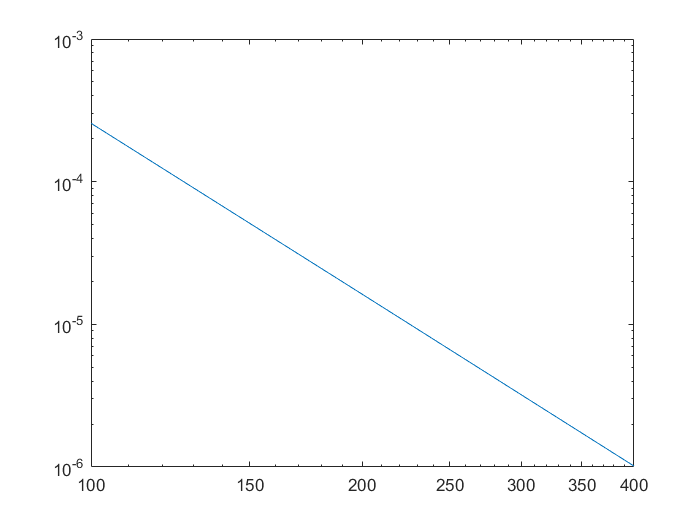

er(3) = sqrt(sum((ic(x)' - u3(:, N)).^2 ./ M));

% ERROR
loglog([100 200 400], er);

er(1)/er(1)

ans = 1

er(1)/er(2)

ans = 15.8338

er(1)/er(3)

ans = 252.7107

Order 4

## 11

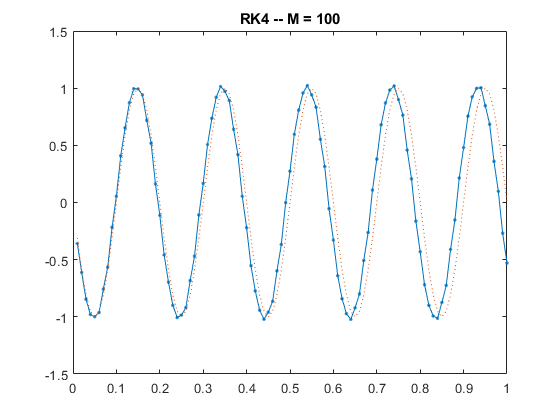

a = 1;
inflow = @(t) sin(10*pi * t);
Q = [100 200 400];
Cn = 1;
g = @(dudx) - a .* dudx;

% INITIAL CONDITION
ic = @(x) 0; % @(x) exp(-0.5 * ((x-0.5) ./ 0.08) .^ 2);


tf = 6;

M = Q(1);
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(tf * 1/dt);
x = (dx:dx:1)';

% SETTING UP INFLOW BOUNDARY CONDITION
% (FROM PERIODIC MATRIX)
A = MAT_DIFF_OPERATOR2(M);
A(M, 1) = 0; 
A(1, M) = 0;
A(M,[M-1 M]) = [-1 1];

q = zeros(M, 1); q(1) = 1;
inflow_diff_component = @(t) -inflow(t)/2 * q;
f = @(t, u) g((A * u + inflow_diff_component(t))./ (dx));

% TIME MARCHING
T1 = 'RK4 -- M = 100';
u1 = RUNGEKUTTA4(M, N, f, 0, dt);
P1 = plot(x, u1(:, N), '.-', x, inflow(-x+tf), ':');
title(T1)
ylim([-1.5 1.5])

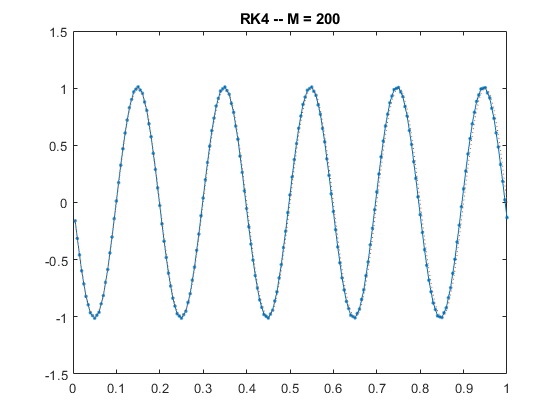

er(1) = sqrt(sum((inflow(-x+tf) - u1(:, N)).^2) ./ M);

M = Q(2);
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(tf * 1/dt);
x = (dx:dx:1)';

% SETTING UP INFLOW BOUNDARY CONDITION
% (FROM PERIODIC MATRIX)
A = MAT_DIFF_OPERATOR2(M);
A(M, 1) = 0; 
A(1, M) = 0;
A(M,[M-1 M]) = [-1 1];

q = zeros(M, 1); q(1) = 1;
inflow_diff_component = @(t) -inflow(t)/2 * q;
f = @(t, u) g((A * u + inflow_diff_component(t))./ (dx));

% TIME MARCHING
T2 = 'RK4 -- M = 200';
u2 = RUNGEKUTTA4(M, N, f, 0, dt);
P2 = plot(x, u2(:, N), '.-', x, inflow(-x+tf), ':');
title(T2)
ylim([-1.5 1.5])

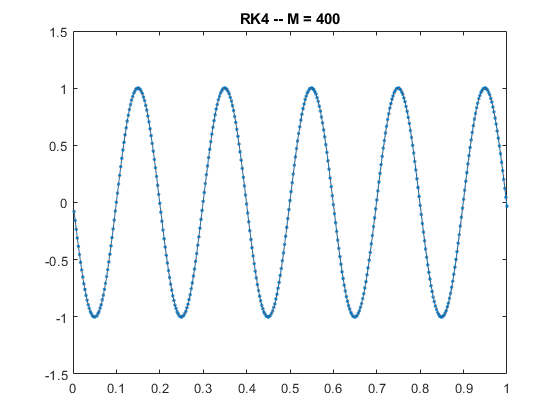

er(2) = sqrt(sum((inflow(-x+tf) - u2(:, N)).^2) ./ M);

M = Q(3);
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(tf * 1/dt);
x = (dx:dx:1)';

% SETTING UP INFLOW BOUNDARY CONDITION
% (FROM PERIODIC MATRIX)
A = MAT_DIFF_OPERATOR2(M);
A(M, 1) = 0; 
A(1, M) = 0;
A(M,[M-1 M]) = [-1 1];

q = zeros(M, 1); q(1) = 1;
inflow_diff_component = @(t) -inflow(t)/2 * q;
f = @(t, u) g((A * u + inflow_diff_component(t))./ (dx));

% TIME MARCHING
T3 = 'RK4 -- M = 400';
u3 = RUNGEKUTTA4(M, N, f, 0, dt);
P3 = plot(x, u3(:, N), '.-', x, inflow(-x+tf), ':');
title(T3)
ylim([-1.5 1.5])

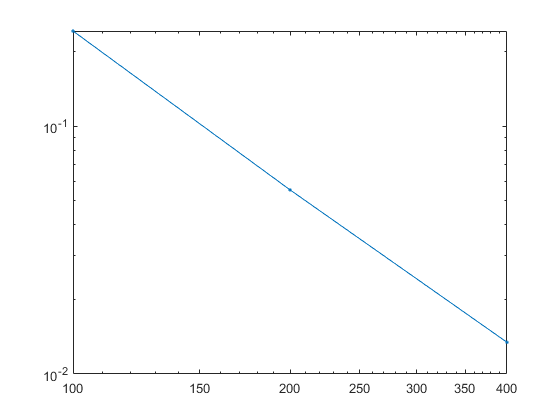

er(3) = sqrt(sum((inflow(-x+tf) - u3(:, N)).^2) ./ M);

% ERROR
loglog([100 200 400], er, '.-');

er(1)/er(1)

ans = 1

er(1)/er(2)

ans = 4.3770

er(1)/er(3)

ans = 18.0532

## 12

clear

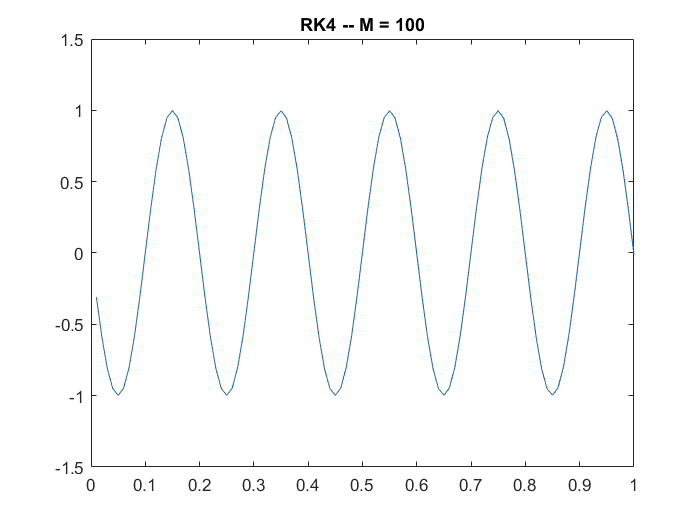

a = 1;
inflow = @(t) sin(10*pi * t);
Q = [100 200 400];
Cn = 1;
g = @(dudx) - a .* dudx;

% INITIAL CONDITION
ic = @(x) 0; % @(x) exp(-0.5 * ((x-0.5) ./ 0.08) .^ 2);


tf = 6;

M = Q(1);
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(tf * 1/dt);
x = (dx:dx:1)';

% SETTING UP INFLOW BOUNDARY CONDITION
% (FROM PERIODIC MATRIX)
A = MAT_DIFF_OPERATOR4(M);
A(M-1:M, 1:2) = 0; 
A(1:2, M-1:M) = 0;
A(1, 1:4) = [-5/6 3/2 -1/2 1/12];
A(M-1, [M-3:M]) = [1/6 -1 1/2 1/3];
A(M, [M-3:M]) = [-1/3 3/2 -3 11/6];

q = zeros(M, 1); q(1:2) = [-1/4 1/12];
inflow_diff_component = @(t) inflow(t) * q;
f = @(t, u) g((A * u + inflow_diff_component(t))./ (dx));

% TIME MARCHING
T1 = 'RK4 -- M = 100';
u1 = RUNGEKUTTA4(M, N, f, 0, dt);
P1 = plot(x, u1(:, N), x, inflow(-x+tf), ':');
title(T1)
ylim([-1.5 1.5])

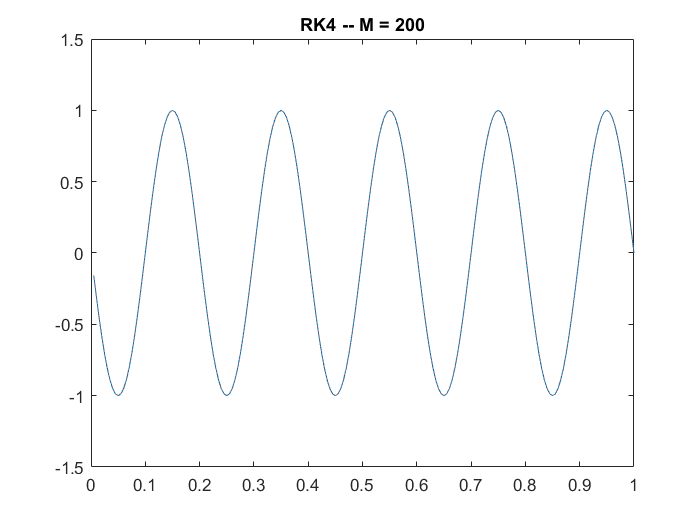

er(1) = sqrt(sum((inflow(-x+tf) - u1(:, N)).^2) ./ M);

M = Q(2);
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(tf * 1/dt);
x = (dx:dx:1)';

% SETTING UP INFLOW BOUNDARY CONDITION
% (FROM PERIODIC MATRIX)
A = MAT_DIFF_OPERATOR4(M);
A(M-1:M, 1:2) = 0; 
A(1:2, M-1:M) = 0;
A(1, 1:4) = [-5/6 3/2 -1/2 1/12];
A(M-1, [M-3:M]) = [1/6 -1 1/2 1/3];
A(M, [M-3:M]) = [-1/3 3/2 -3 11/6];

q = zeros(M, 1); q(1:2) = [-1/4 1/12];
inflow_diff_component = @(t) inflow(t) * q;
f = @(t, u) g((A * u + inflow_diff_component(t))./ (dx));

% TIME MARCHING
T2 = 'RK4 -- M = 200';
u2 = RUNGEKUTTA4(M, N, f, 0, dt);
P2 = plot(x, u2(:, N), x, inflow(-x+tf), ':');
title(T2)
ylim([-1.5 1.5])

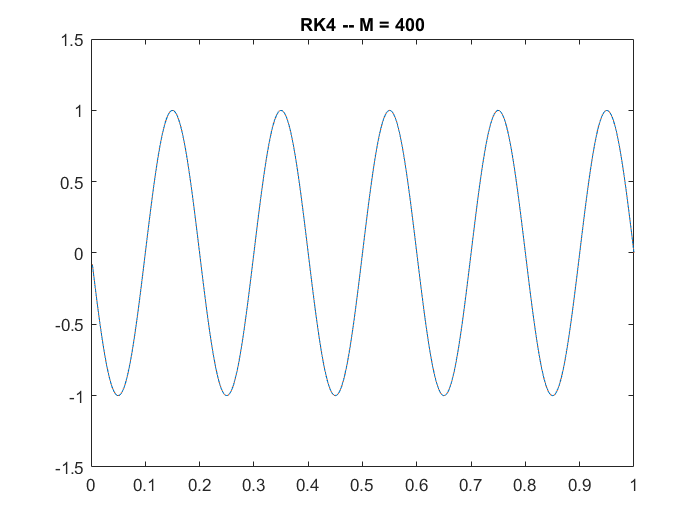

er(2) = sqrt(sum((inflow(-x+tf) - u2(:, N)).^2) ./ M);

M = Q(3);
dx = 1 / M;
dt = Cn * dx ./ a;
N = round(tf * 1/dt);
x = (dx:dx:1)';

% SETTING UP INFLOW BOUNDARY CONDITION
% (FROM PERIODIC MATRIX)
A = MAT_DIFF_OPERATOR4(M);
A(M-1:M, 1:2) = 0; 
A(1:2, M-1:M) = 0;
A(1, 1:4) = [-5/6 3/2 -1/2 1/12];
A(M-1, [M-3:M]) = [1/6 -1 1/2 1/3];
A(M, [M-3:M]) = [-1/3 3/2 -3 11/6];

q = zeros(M, 1); q(1:2) = [-1/4 1/12];
inflow_diff_component = @(t) inflow(t) * q;
f = @(t, u) g((A * u + inflow_diff_component(t))./ (dx));

% TIME MARCHING
T3 = 'RK4 -- M = 400';
u3 = RUNGEKUTTA4(M, N, f, 0, dt);
P3 = plot(x, u3(:, N), x, inflow(-x+tf), ':');
title(T3)
ylim([-1.5 1.5])

er(3) = sqrt(sum((inflow(-x+tf) - u3(:, N)).^2) ./ M);

% ERROR
loglog([100 200 400], er);
er(1)/er(1)

ans = 1

er(1)/er(2)

ans = 16.5247

er(1)/er(3)

ans = 275.5188

clear